# 3D microseismic event location with Diffraction Stack (DS) method

## Introduction

Microseismic event location with the Diffraction Stack method. See description of the method in

Zhebel, Oksana. "Imaging of seismic events: The role of imaging conditions, acquisition geometry and source mechanisms." (2014).

[http://ediss.sub.uni-hamburg.de/volltexte/2014/7004/](http://ediss.sub.uni-hamburg.de/volltexte/2014/7004/)

**Author**: Ivan Abakumov

**Publication date**: 04th December 2018

**E-mail**: [ivan.abakumov@fu-berlin.de](mailto:ivan.abakumov@fu-berlin.de)

## Add MLIB library

clear; close all; clc;
%mlibfolder = '/remote/data/ivan/share/MLIB';
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load acquisition and velocity model

G = MLD('/data/ivan/share/MARATHON/Marathon_G_file_100ft.mat'); 
velmod = MLD('/data/ivan/share/MARATHON/Marathon_velmod_100ft.mat');
acq = MLD('/data/ivan/share/MARATHON/Marathon_surf_acquisition.mat');


%PerfB = MLD('/data/ivan/share/MARATHON/Marathon_Perforation_Locations_borehole.mat');
%FracB = MLD('/data/ivan/share/MARATHON/Marathon_Fracture_Locations_borehole.mat');    
%PerfS = MLD('/data/ivan/share/MARATHON/Marathon_Perforation_Locations_surface.mat');
%FracS = MLD('/data/ivan/share/MARATHON/Marathon_Fracture_Locations_surface.mat');   

ftm = 0.3048006096012192;  % US survey foot

G.t0 = 0;
G.dt = 0.004;
G.nt = 625;
Fs = 1/G.dt;
acq.grx = x2grid(acq.rx,G.x0,G.dx,G.nx);
acq.gry = x2grid(acq.ry,G.y0,G.dy,G.ny);

G.setGrid;
Gold = G.oldGrid;

## Load windowed PSET file

required = 1;
if(required)
    
    % example fracture event
    sufolder = '/remote/data/MARATHON/Surface_Data/Time_Windowed_Traces/Fractures/Full_Processing_No_Moveout/C4/';
    filename = '2013093_113435_023.pset';
    
    % example perforation shot 
%    sufolder = '/remote/data/MARATHON/Surface_Data/Time_Windowed_Traces/Perforations/Full_Processing_No_Moveout/';
    %filename = '2013092_033110_129.pset';
%    filename = '2013095_184125_015.pset';
                

    
    
    Data=read_segy_file([sufolder filename]);
   
end

Seismic data shifted since header "lag" is not identically zero.
Lag varies from 2500 to 2500


## Data preprocessing

nData = zeros(625,1547);

for i=1:1547

    trace = Data.traces(:,i);
    
    
    Nl = 125;               % sum range for LTA  500 ms 
    Ns = 15;                % sum range for STA  60 ms
    STA = movmean(trace.^2,[0, Ns-1]);
    LTA = movmean(trace.^2,[Nl-1, 0]);
    STALTA = STA./LTA;
    STALTA(1:15) = 0;
    nData(:,i) = STALTA;
    
end


## Plot data

    figure(1)
    stan = 1:1547;
    pcolor(stan,G.tt,nData);
    shading interp
    set(gca, 'Ydir', 'reverse')
    caxis([0 3])
    colormap('jet');
    hold on
    for i=1:length(acq.linebr)
        plot(acq.linebr(i)*ones(size(G.tt)), G.tt, '-red', 'Linewidth',2);
    end
    for i=1:length(acq.linedf)
        plot(acq.linedf(i)*ones(size(G.tt)), G.tt, '--blue','Linewidth',1);
    end

## Compute traveltimes

recind = 1:5:1547; 
TTI = zeros(G.nx,G.ny,G.nz,length(recind));

for j=1:length(recind)
    i = recind(j);
    Source = [acq.rx(i), acq.ry(i), G.z0]; 
    tti = FSM3D(Gold, Source, velmod);
    TTI(:,:,:,j) = tti; 
end
    

## Compute DS image

ttzero = -0.5:0.01:1.0;        
J = zeros(G.nx,G.ny,G.nz,length(ttzero));

for k=1:length(ttzero)

    tzero = ttzero(k);
    I = zeros(G.nx,G.ny,G.nz);
    
    for j=1:length(recind)
        i = recind(j);
        
        trace = nData(:,i);
        %trace = abs(hilbert(trace)); 
        
        tti = TTI(:,:,:,j); 
        ntp=round((tzero+tti)/G.dt);
        ntp=min(max(ntp,1),G.nt); 
        I = I + trace(ntp);
    end
    J(:,:,:,k) = I; 
    disp(k) 
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



JJ = J; 
[maxpdf, maxind] = max(JJ(:));
[maxi,maxj,maxk,maxt] = ind2sub(size(JJ),maxind);
J = JJ(:,:,:,maxt);

## Plot results

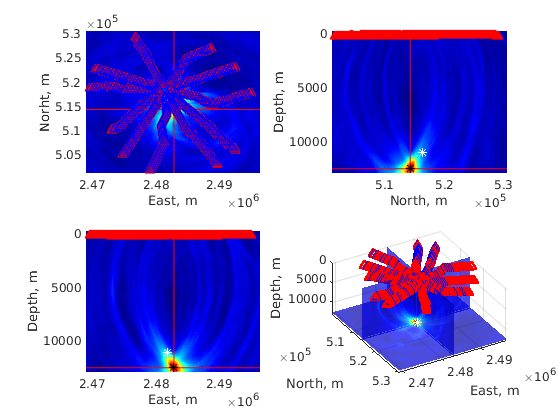

loc.x = 2481900.5; 
loc.y = 516310.09; 
loc.z = 11125.59;


figure(312847);
subplot(2,2,1);
pcolor(G.xx,G.yy,squeeze(J(:,:,maxk)'));
shading interp
axis xy;
xlabel('East, m');
ylabel('Norht, m');
hold on
plot([G.xx(1),G.xx(end)],[G.yy(maxj),G.yy(maxj)],'r')
plot([G.xx(maxi),G.xx(maxi)],[G.yy(1),G.yy(end)],'r')
plot(G.xx(maxi),G.yy(maxj),'k*')
plot(acq.rx,acq.ry,'r^');
plot(loc.x,loc.y,'w*');
plot(acq.rx(recind),acq.ry(recind),'b^');


subplot(2,2,2);
pcolor(G.yy,G.zz,squeeze(J(maxi,:,:))');
shading interp
axis xy;
xlabel('North, m');
ylabel('Depth, m');
hold on
plot([G.yy(maxj),G.yy(maxj)],[G.zz(1),G.zz(end)],'r')
plot([G.yy(1),G.yy(end)],[G.zz(maxk),G.zz(maxk)],'r')
plot(G.yy(maxj),G.zz(maxk),'k*')
plot(acq.ry,acq.rz,'r^');
plot(loc.y,loc.z,'w*');
plot(acq.rx(recind),acq.ry(recind),'b^');
set(gca,'Ydir','reverse'); 

subplot(2,2,3);
pcolor(G.xx,G.zz,squeeze(J(:,maxj,:))');
shading interp
axis xy;
xlabel('East, m');
ylabel('Depth, m');
hold on
plot([G.xx(1),G.xx(end)],[G.zz(maxk),G.zz(maxk)],'r')
plot([G.xx(maxi),G.xx(maxi)],[G.zz(1),G.zz(end)],'r')
plot(G.xx(maxi),G.zz(maxk),'k*')
plot(acq.rx,acq.rz,'r^');
plot(loc.x,loc.z,'w*');
plot(acq.rx(recind),acq.ry(recind),'b^');
set(gca,'Ydir','reverse'); 

subplot(2,2,4);
xs=G.xx(maxi);
ys=G.yy(maxj);
zs=G.zz(maxk);
h=slice(G.yy,G.xx,G.zz,J,ys,xs,zs); 
set(h,'FaceColor','interp','EdgeColor','none') 
alpha(.7); 
axis([G.y0 G.my G.x0 G.mx G.z0 G.mz]);
set(gca,'Zdir','reverse'); 
axis image; 
view(60,30);
hold on
plot3(acq.ry,acq.rx,acq.rz,'r^');
plot3(acq.ry(recind),acq.rx(recind),acq.rz(recind),'b^');
plot3(G.yy(maxj),G.xx(maxi),G.zz(maxk),'k*')
plot3(loc.y, loc.x, loc.z, 'w*');
xlabel('North, m')
ylabel('East, m')
zlabel('Depth, m')
colormap('jet')